% Load Results

results = zeros(97,9);
%       number of calls per message symbol      lookahead symbols
%      -----------------------------------  ---------------------
%  ns       min      avg      med      max   min    avg  med  max
% ---  -------- -------- -------- --------  ---- ------ ---- ----

for i = 3:100
    results(i-2,:) = load(strcat("results\",sprintf('%04.0f', i))); 
end


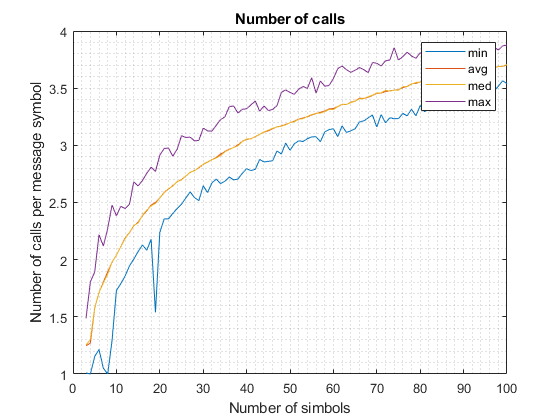

% Plot Number of Calls
for k= 1:4
    plot(results(:,1),results(:,1+k));
    hold on;
end
hold off;
legend("min","avg","med","max");
title("Number of calls");
xlabel("Number of simbols");
ylabel("Number of calls per message symbol");
grid("minor");

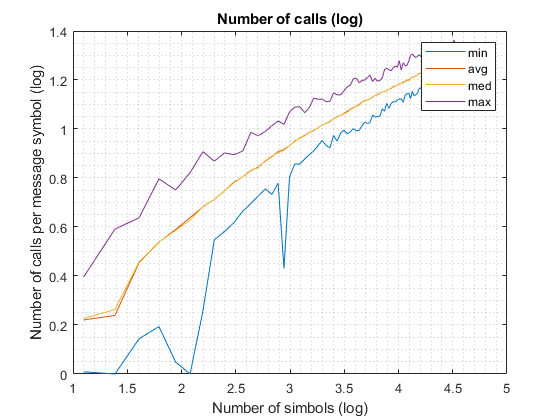

% Plot Number of Calls (log)
for k= 1:4
    plot(log(results(:,1)),log(results(:,1+k)));
    hold on;
end
hold off;
legend("min","avg","med","max");
title("Number of calls (log)");
xlabel("Number of simbols (log)");
ylabel("Number of calls per message symbol (log)");
grid("minor");

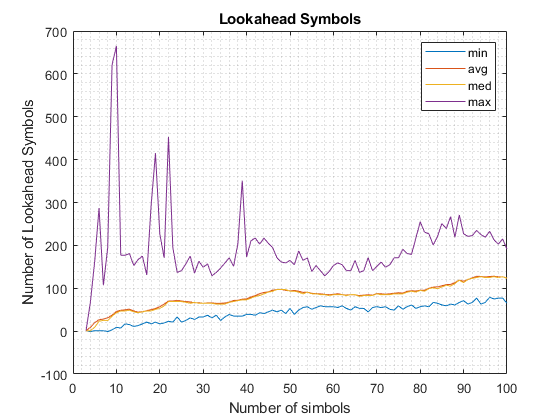

% Plot Number of Lookahead Symbols
for k= 1:4
    plot(results(:,1),results(:,5+k));
    hold on;
end
hold off;
legend("min","avg","med","max");
title("Lookahead Symbols");
xlabel("Number of simbols");
ylabel("Number of Lookahead Symbols");
grid("minor");

% Plot Number of Lookahead Symbols (log)
for k= 1:4
    plot(log(results(:,1)),log(results(:,5+k)));
    hold on;
end

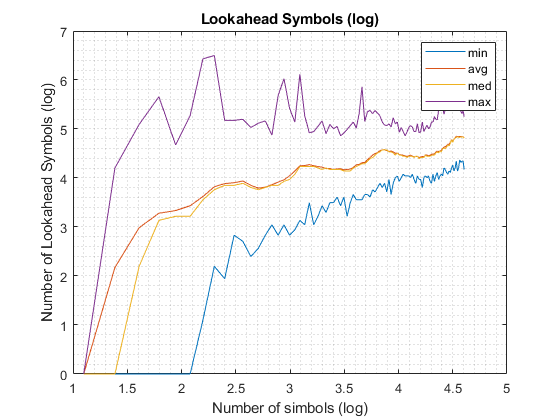

hold off;
legend("min","avg","med","max");
title("Lookahead Symbols (log)");
xlabel("Number of simbols (log)");
ylabel("Number of Lookahead Symbols (log)");
grid("minor");

% Load Times
time = readcell(strcat("results\times"));
times = [str2double(string(time(:,1))),str2double(regexprep(regexprep(time(:,4),',',"."),'s',""))];

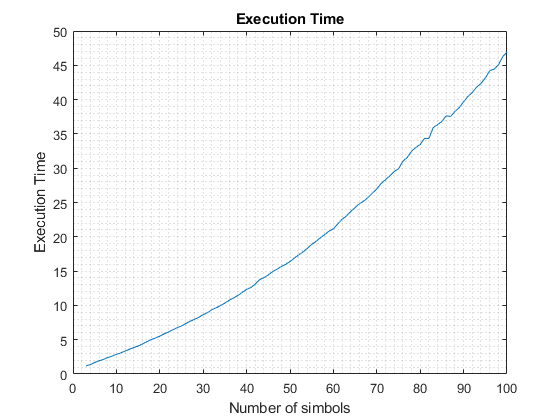

% Plot Execution Time
plot(times(:,1),times(:,2));
title("Execution Time");
xlabel("Number of simbols");
ylabel("Execution Time");
grid("minor");

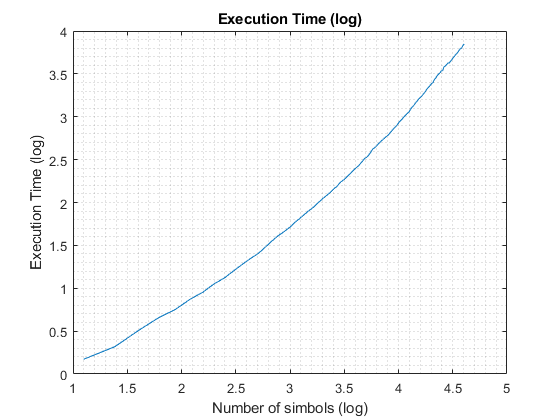

% Plot Execution Time (log)
plot(log(times(:,1)),log(times(:,2)));
title("Execution Time (log)");
xlabel("Number of simbols (log)");
ylabel("Execution Time (log)");
grid("minor");

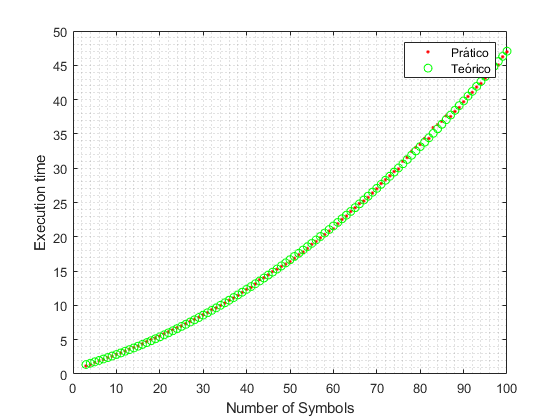

% Complexidade Computacional
x = times(:,1);                                                     % extract the first column
y = times(:,2);                                                     % extract the second column
X = [ x.^2, x, 0*x+1 ];                                             % build the X matrix for y(x) = Ax^2 + Bx + C 
w = pinv(X)*y;                                                      % optimal solution (could also be written as w = X \ y;)
e = y-X*w;                                                          % optional: compute the errors vector
format long;
w;                                                                  % print w --- A = w(1), B = w(2), and C = w(3)
norm(e);                                                            % optional: print the norm of the error vector (square root of the sum of squares)
plot(x,y,'.r',x,X*w,'og');                                          % plot the original data and its best least squares approximation
grid("minor");
xlabel("Number of Symbols");
ylabel("Execution time");
legend("Prático","Teórico");